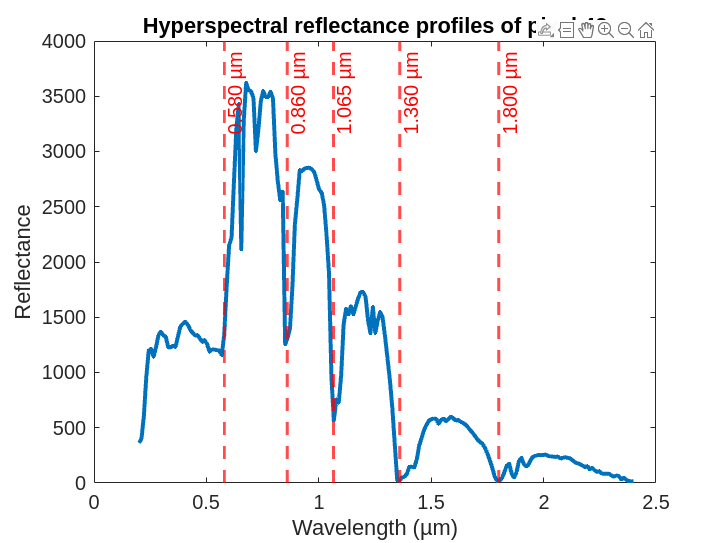

clear
format compact
close all

load Salinas_Data

% Modify the shape of the data set
[p,n,l]=size(Salinas_Image);
X_total=reshape(Salinas_Image, p*n,l);
L=reshape(Salinas_Labels,p*n,1);
existed_L=(L>0);
X=X_total(existed_L,:);
I = size(X, 1);


% Randomly picked pixel 42 for a single plot
j = 42;
figure(2);
plot(linspace(0.2, 2.4, 204), X(j, :), "LineWidth", 2);
xlabel('Wavelength (µm)')
ylabel('Reflectance')
title(sprintf('Hyperspectral reflectance profiles of pixel %d', j))

red_line_positions = [0.58, 0.86, 1.065, 1.36, 1.8];
for r = 1:length(red_line_positions)
    % Add the vertical line
    xline(red_line_positions(r), '--', 'Color', 'r', 'LineWidth', 1.5);
    
    % Add a text label
    text(red_line_positions(r), max(X(j, :)) * 0.975, ...
         sprintf('%.3f µm', red_line_positions(r)), ...
         'HorizontalAlignment', 'center', ...
         'VerticalAlignment', 'top', ...
         'Rotation', 90, ...
         'FontSize', 10, ...
         'Color', 'r');
end

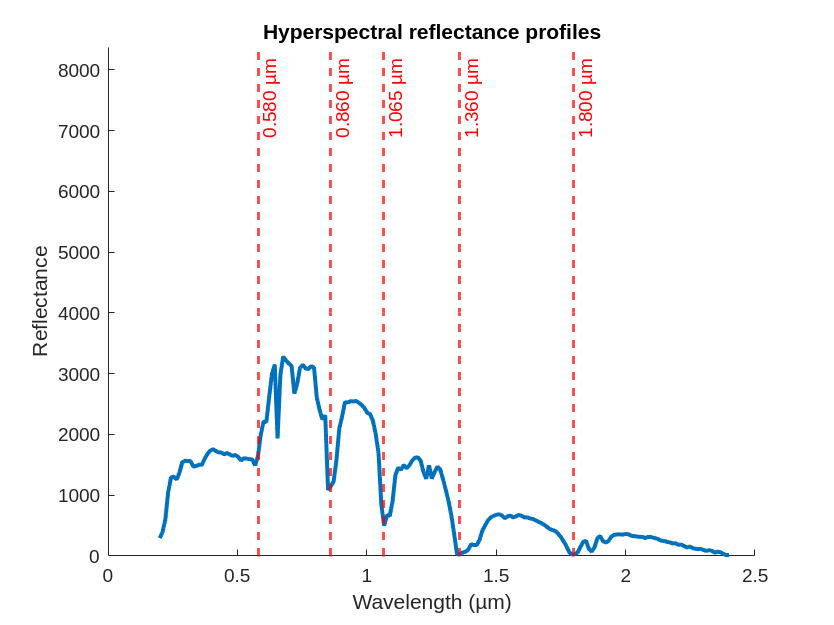

% Get the actual wavelengths
bands = linspace(0.2, 2.4, 204);

% Bool check so the "movie" won't play every time, it takes forever
run_all = true;
% Plot the reflectance profiles
if run_all
    figure(1);
    
    % Static elements
    xlabel('Wavelength (µm)');
    ylabel('Reflectance');
    title('Hyperspectral reflectance profiles');
    ylim([0, max(max(X))]);
    hold on;

    red_line_positions = [0.58, 0.86, 1.065, 1.36, 1.8];
    for r = 1:length(red_line_positions)
        xline(red_line_positions(r), '--', 'Color', 'r', 'LineWidth', 1.5);
        text(red_line_positions(r), max(max(X)) * 0.9, ...
             sprintf('%.3f µm', red_line_positions(r)), ...
             'HorizontalAlignment', 'center', ...
             'VerticalAlignment', 'top', ...
             'Rotation', 90, ...
             'FontSize', 10, ...
             'Color', 'r');
    end

    profile_plot = plot(nan, nan, "LineWidth", 2);

    for i = 1:I
        set(profile_plot, 'XData', bands, 'YData', X(i, :));
        pause(0.001);
    end
    hold off;
end